# Berechnung einer Näherung der Zahl $\pi$

Der Umfang eines Kreises mit Radius 1 ist $2\cdot\pi
$.

Zur Bestimmung des Umfangs des  Einheitskreises kann man  in den Kreis $n$-Ecke einzeichnen und deren Umfang $U(n)$ berechnen. 

Wenn man mit einem Dreieck startet und im weiteren jeweils die Anzahl der Seiten verdoppelt, ergibt sich folgendes Bild

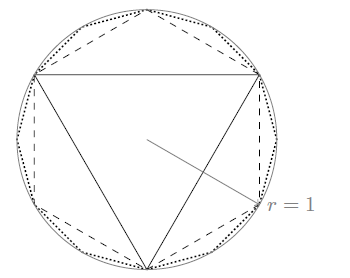

Man sieht leicht, dass der Umfang des Dreiecks $3\cdot\sqrt{3}$. Dies ist der Startwert.

U3 = 3 * sqrt(3);

Zur Berechnung des Umfangs  des $3\ast2^{k-1}$-Ecks,  $a_k:=U(3*2^{k-1})$,  $k=1,2,3,\ldots$, verwenden wir die folgende Formel 

$a_{k+1}=\sqrt{12\cdot 2^{k-1} \cdot \left(6\cdot2^{k-1} - \sqrt{\bigl(6\cdot 2^{k-1}\bigr)^2-a^2_k}\right)}$ .

Es werden die ersten $m$ Glieder der Folge berechnet:

m=30

m = 30

for k=1:m-1 
    if (k==1) a_alt=U3; end;
    a_neu= sqrt(12*2^(k-1)*(6*2^(k-1) - sqrt((6*2^(k-1))^2-(a_alt)^2)))
    a_alt=a_neu;
end

a_neu = 6

a_neu = 6.2117

a_neu = 6.2653

a_neu = 6.2787

a_neu = 6.2821

a_neu = 6.2829

a_neu = 6.2831

a_neu = 6.2832

a_neu = 6.2832

a_neu = 6.2832

a_neu = 6.2832

a_neu = 6.2832

a_neu = 6.2832

a_neu = 6.2832

a_neu = 6.2832

a_neu = 6.2832

a_neu = 6.2832

a_neu = 6.2832

a_neu = 6.2832

a_neu = 6.2831

a_neu = 6.2833

a_neu = 6.2824

a_neu = 6.2899

a_neu = 6.3048

a_neu = 6.2450

a_neu = 6

a_neu = 6.9282

a_neu = 0

a_neu = 0

format long;
disp('-------------------');

-------------------


Approximation_von_2pi=a_neu

Approximation_von_2pi =      0


format short;
Fehler=abs(a_neu-2*pi)

Fehler = 6.2832

disp('-------------------');

-------------------


Für Werte $m\geq 29$ ist die resultierende  Approximation  offensichtlich nicht befriedigend. 

Wir betrachten ein alternatives Vorgehen. Dazu definieren wir eine neue Folge

    
$$b_1=a_1=U(3)$$


und

$b_{k+1}=
\sqrt{\frac{12\cdot 2^{k-1} \cdot b^2_k}{6\cdot2^{k-1} + \sqrt{(6\cdot 2^{k-1})^2-{b^2_k}}}
$,   $k\geq 1$.

Es gilt $a_k=b_k$ für $k=1,2,\ldots$ (kann mit Induktion gezeigt werden).

Es werden die ersten $p$ Glieder dieser Folge berechnet:

p=30

p = 30

format short;
for k=1:p-1
    if (k==1) b_alt=U3; end;
    b_neu = sqrt((12*2^(k-1)*b_alt^2)/(6*2^(k-1)+sqrt((6*2^(k-1))^2-b_alt^2)))
    b_alt=b_neu;
end

b_neu = 6

b_neu = 6.2117

b_neu = 6.2653

b_neu = 6.2787

b_neu = 6.2821

b_neu = 6.2829

b_neu = 6.2831

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

b_neu = 6.2832

format long;
disp('-------------------');

-------------------


Approximation_von_2pi=b_neu

Approximation_von_2pi =    6.283185307179586


format short;
Fehler=abs(b_neu-2*pi)

Fehler = 0

# Aktivität:

Variieren Sie die Parameter $m$ und $p$ (ggf. auch $m=p$) und erklären Sie die Unterschiede der Ergebnisse der beiden Algorithmen (siehe auch Buch).